rng(14);
n=500;
% rand1 = exprnd(.16,[1,floor(n/3)]);
% rand1 = rand1(rand1<=0.6);
% rand1 = rand1(rand1>0);
% rand3 = exprnd(0.12,[1,floor(n/3)])+0.5;
% rand3 = rand3(rand3<=1);
% rand3 = rand3(rand3>0.5);
lower = 0;
peak = 0.2;
upper = 1;
pd = makedist('Triangular','A',lower,'B',peak,'C',upper);
y = random(pd,1,n);

% y = ([rand1])

% y = y(y<=1);
sum(y<0)

ans = 0

sum(y>1)

ans = 0



% d = 11;
% knots = [-0.0750:0.025:1.025];
knots = [-0.020:0.03:1.025];
knots(end-1) = 1;
knots(2) = 0;
constraintFunc = @(x) logspline_constraint(knots, x);
options = optimoptions('fsolve','Display','none','TolFun', 1e-10);

flag=11;
solve_this = @(a) (constraintFunc(a));
% initial = [-2.5, log(0.25), log(0.6),log(1.4), log(2.2), log(1.5),...
%     log(2.4), log(2.1), log(1.1), ...
%     log(1.15),log(1.2),log(0.7), log(0.75), log(0.8),...
%     log(0.4),log(0.5), log(0.6), log(0.5), log(0.4), log(0.3), ...
%     -2.5];
initial = [-2.5, log(0.25),log(0.4),log(0.6),log(1.5),log(1.4),log(1.5), log(2.2),log(2.3), log(1.5),...
    log(2.4),log(2.5), log(2.1),log(2), log(1.1), log(1.2), ...
    log(1.15),log(1.2),log(1.25),log(0.7), log(0.75), log(0.8),log(0.85),...
    log(0.4),log(0.45), log(0.5), log(0.55), log(0.6), log(0.55), log(0.5), log(0.4),log(0.45), log(0.3), ...
    -2.5];
initial_guess = fsolve(solve_this, initial, options)

initial_guess =    -2.5017   -1.3919   -0.9248   -0.5252    0.3781    0.3063    0.3721    0.7446    0.7881    0.3687    0.8283    0.8657    0.6969    0.6544    0.0691    0.1576    0.1152    0.1571    0.1992   -0.3733   -0.3035   -0.2400   -0.1784   -0.9262   -0.8080   -0.7037   -0.6094   -0.5231   -0.6094   -0.7035   -0.9252   -0.8114   -1.2113   -2.5000




syms func2(x)
chosen_theta = initial_guess

chosen_theta =    -2.5017   -1.3919   -0.9248   -0.5252    0.3781    0.3063    0.3721    0.7446    0.7881    0.3687    0.8283    0.8657    0.6969    0.6544    0.0691    0.1576    0.1152    0.1571    0.1992   -0.3733   -0.3035   -0.2400   -0.1784   -0.9262   -0.8080   -0.7037   -0.6094   -0.5231   -0.6094   -0.7035   -0.9252   -0.8114   -1.2113   -2.5000


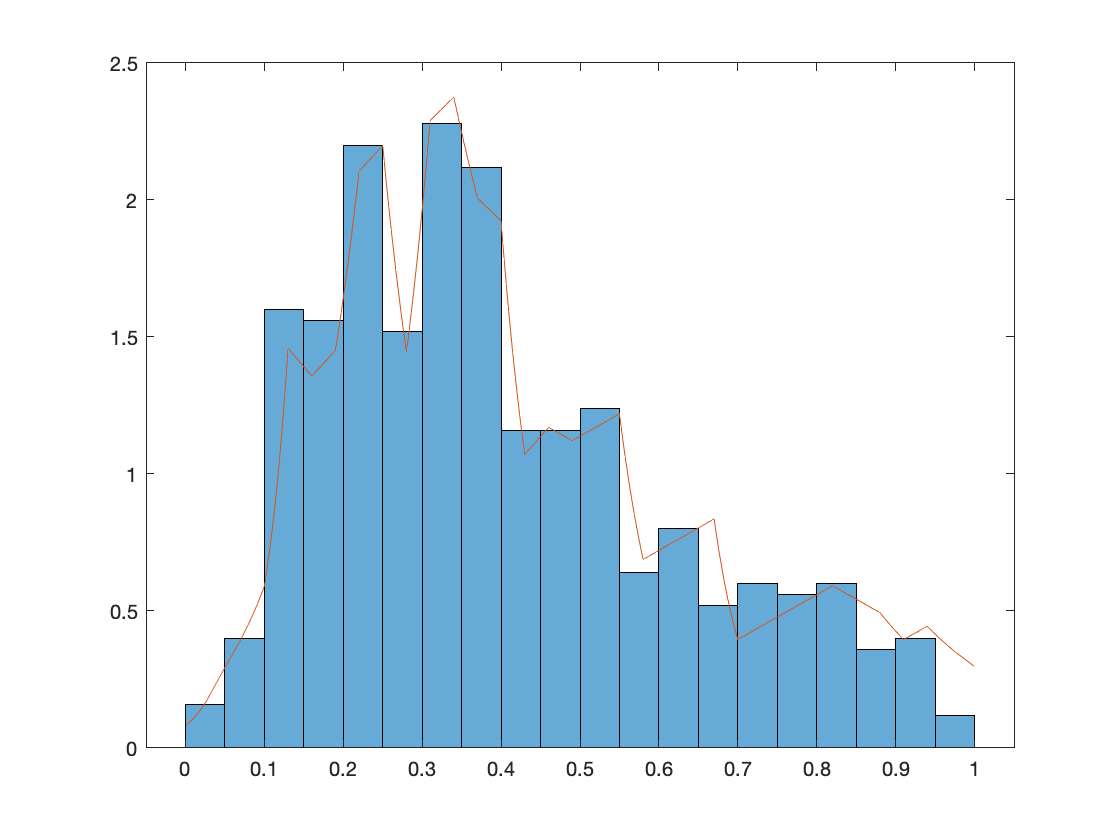

func2(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
    (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))), ...
    (knots(10) < x)&(x <= knots(11)),exp(chosen_theta(10)*(x-knots(10))/(knots(11)-knots(10)) + chosen_theta(9)*(knots(11)-x)/(knots(11)-knots(10))), ...
    (knots(11) < x)&(x <= knots(12)),exp(chosen_theta(11)*(x-knots(11))/(knots(12)-knots(11)) + chosen_theta(10)*(knots(12)-x)/(knots(12)-knots(11))), ...
    (knots(12) < x)&(x <= knots(13)),exp(chosen_theta(12)*(x-knots(12))/(knots(13)-knots(12)) + chosen_theta(11)*(knots(13)-x)/(knots(13)-knots(12))), ...
    (knots(13) < x)&(x <= knots(14)),exp(chosen_theta(13)*(x-knots(13))/(knots(14)-knots(13)) + chosen_theta(12)*(knots(14)-x)/(knots(14)-knots(13))), ...
    (knots(14) < x)&(x <= knots(15)),exp(chosen_theta(14)*(x-knots(14))/(knots(15)-knots(14)) + chosen_theta(13)*(knots(15)-x)/(knots(15)-knots(14))), ...
    (knots(15) < x)&(x <= knots(16)),exp(chosen_theta(15)*(x-knots(15))/(knots(16)-knots(15)) + chosen_theta(14)*(knots(16)-x)/(knots(16)-knots(15))), ...
    (knots(16) < x)&(x <= knots(17)),exp(chosen_theta(16)*(x-knots(16))/(knots(17)-knots(16)) + chosen_theta(15)*(knots(17)-x)/(knots(17)-knots(16))), ...
    (knots(17) < x)&(x <= knots(18)),exp(chosen_theta(17)*(x-knots(17))/(knots(18)-knots(17)) + chosen_theta(16)*(knots(18)-x)/(knots(18)-knots(17))), ...
    (knots(18) < x)&(x <= knots(19)),exp(chosen_theta(18)*(x-knots(18))/(knots(19)-knots(18)) + chosen_theta(17)*(knots(19)-x)/(knots(19)-knots(18))), ...
    (knots(19) < x)&(x <= knots(20)),exp(chosen_theta(19)*(x-knots(19))/(knots(20)-knots(19)) + chosen_theta(18)*(knots(20)-x)/(knots(20)-knots(19))), ...
    (knots(20) < x)&(x <= knots(21)),exp(chosen_theta(20)*(x-knots(20))/(knots(21)-knots(20)) + chosen_theta(19)*(knots(21)-x)/(knots(21)-knots(20))), ...
    (knots(21) < x)&(x <= knots(22)),exp(chosen_theta(21)*(x-knots(21))/(knots(22)-knots(21)) + chosen_theta(20)*(knots(22)-x)/(knots(22)-knots(21))), ...
    (knots(22) < x)&(x <= knots(23)),exp(chosen_theta(22)*(x-knots(22))/(knots(23)-knots(22)) + chosen_theta(21)*(knots(23)-x)/(knots(23)-knots(22))), ...
    (knots(23) < x)&(x <= knots(24)),exp(chosen_theta(23)*(x-knots(23))/(knots(24)-knots(23)) + chosen_theta(22)*(knots(24)-x)/(knots(24)-knots(23))), ...
    (knots(24) < x)&(x <= knots(25)),exp(chosen_theta(24)*(x-knots(24))/(knots(25)-knots(24)) + chosen_theta(23)*(knots(25)-x)/(knots(25)-knots(24))), ...
    (knots(25) < x)&(x <= knots(26)),exp(chosen_theta(25)*(x-knots(25))/(knots(26)-knots(25)) + chosen_theta(24)*(knots(26)-x)/(knots(26)-knots(25))), ...
    (knots(26) < x)&(x <= knots(27)),exp(chosen_theta(26)*(x-knots(26))/(knots(27)-knots(26)) + chosen_theta(25)*(knots(27)-x)/(knots(27)-knots(26))), ...
    (knots(27) < x)&(x <= knots(28)),exp(chosen_theta(27)*(x-knots(27))/(knots(28)-knots(27)) + chosen_theta(26)*(knots(28)-x)/(knots(28)-knots(27))), ...
    (knots(28) < x)&(x <= knots(29)),exp(chosen_theta(28)*(x-knots(28))/(knots(29)-knots(28)) + chosen_theta(27)*(knots(29)-x)/(knots(29)-knots(28))), ...
    (knots(29) < x)&(x <= knots(30)),exp(chosen_theta(29)*(x-knots(29))/(knots(30)-knots(29)) + chosen_theta(28)*(knots(30)-x)/(knots(30)-knots(29))), ...
    (knots(30) < x)&(x <= knots(31)),exp(chosen_theta(30)*(x-knots(30))/(knots(31)-knots(30)) + chosen_theta(29)*(knots(31)-x)/(knots(31)-knots(30))), ...
    (knots(31) < x)&(x <= knots(32)),exp(chosen_theta(31)*(x-knots(31))/(knots(32)-knots(31)) + chosen_theta(30)*(knots(32)-x)/(knots(32)-knots(31))), ...
    (knots(32) < x)&(x <= knots(33)),exp(chosen_theta(32)*(x-knots(32))/(knots(33)-knots(32)) + chosen_theta(31)*(knots(33)-x)/(knots(33)-knots(32))), ...
    (knots(33) < x)&(x <= knots(34)),exp(chosen_theta(33)*(x-knots(33))/(knots(34)-knots(33)) + chosen_theta(32)*(knots(34)-x)/(knots(34)-knots(33))), ...
    (knots(34) < x)&(x <= knots(35)),exp(chosen_theta(34)*(x-knots(34))/(knots(35)-knots(34)) + chosen_theta(33)*(knots(35)-x)/(knots(35)-knots(34))));
histogram(y, 'Normalization','pdf','BinWidth',0.05)
hold on
fplot(func2, [0,1])
hold off

% saveas(gcf,'InitialHist.png')


num_iters = 15000;
burn_in = 1;
proposal_scale = 1e-2

proposal_scale = 0.0100

% 
ll_function = @(x) ll_density(x, knots, y);
constraintFunc = @(x) logspline_constraint(knots, x);
dConstraintFunc = @(x) dlogspline_constraint(knots, x);
[samples, accepts] = runConstrainedMH(num_iters, burn_in, ...
    proposal_scale, initial_guess', ll_function, ...
    constraintFunc, dConstraintFunc)
mean(accepts)
sum(accepts)
save("MH_logsplineDraws_other.mat",'samples');

plot(accepts)

% I will need to get a point estimator at some point, but for now let's
% just choose a theta and see if I can plot it.
samples = matfile("MH_logsplineDraws_other.mat");
samples = samples.samples;
mean_value = mean(samples')';
mean_diff = samples - mean_value;
[~,num_cols] = size(mean_diff);
mag_mean_diff = zeros(1,num_cols);
for i=1:num_cols
    mag_mean_diff(i) = norm(mean_diff(:,i), 2);
end
[~,min_index] = min(mag_mean_diff);

% fplot(y, [0,1])
[~,num_samples] = size(samples);
character_array = ["1"];
prev_sample = samples(:,1);
chosen_theta = initial_guess;
func1(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
    (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))), ...
    (knots(10) < x)&(x <= knots(11)),exp(chosen_theta(10)*(x-knots(10))/(knots(11)-knots(10)) + chosen_theta(9)*(knots(11)-x)/(knots(11)-knots(10))), ...
    (knots(11) < x)&(x <= knots(12)),exp(chosen_theta(11)*(x-knots(11))/(knots(12)-knots(11)) + chosen_theta(10)*(knots(12)-x)/(knots(12)-knots(11))), ...
    (knots(12) < x)&(x <= knots(13)),exp(chosen_theta(12)*(x-knots(12))/(knots(13)-knots(12)) + chosen_theta(11)*(knots(13)-x)/(knots(13)-knots(12))), ...
    (knots(13) < x)&(x <= knots(14)),exp(chosen_theta(13)*(x-knots(13))/(knots(14)-knots(13)) + chosen_theta(12)*(knots(14)-x)/(knots(14)-knots(13))), ...
    (knots(14) < x)&(x <= knots(15)),exp(chosen_theta(14)*(x-knots(14))/(knots(15)-knots(14)) + chosen_theta(13)*(knots(15)-x)/(knots(15)-knots(14))), ...
    (knots(15) < x)&(x <= knots(16)),exp(chosen_theta(15)*(x-knots(15))/(knots(16)-knots(15)) + chosen_theta(14)*(knots(16)-x)/(knots(16)-knots(15))), ...
    (knots(16) < x)&(x <= knots(17)),exp(chosen_theta(16)*(x-knots(16))/(knots(17)-knots(16)) + chosen_theta(15)*(knots(17)-x)/(knots(17)-knots(16))), ...
    (knots(17) < x)&(x <= knots(18)),exp(chosen_theta(17)*(x-knots(17))/(knots(18)-knots(17)) + chosen_theta(16)*(knots(18)-x)/(knots(18)-knots(17))), ...
    (knots(18) < x)&(x <= knots(19)),exp(chosen_theta(18)*(x-knots(18))/(knots(19)-knots(18)) + chosen_theta(17)*(knots(19)-x)/(knots(19)-knots(18))), ...
    (knots(19) < x)&(x <= knots(20)),exp(chosen_theta(19)*(x-knots(19))/(knots(20)-knots(19)) + chosen_theta(18)*(knots(20)-x)/(knots(20)-knots(19))), ...
    (knots(20) < x)&(x <= knots(21)),exp(chosen_theta(20)*(x-knots(20))/(knots(21)-knots(20)) + chosen_theta(19)*(knots(21)-x)/(knots(21)-knots(20))), ...
    (knots(21) < x)&(x <= knots(22)),exp(chosen_theta(21)*(x-knots(21))/(knots(22)-knots(21)) + chosen_theta(20)*(knots(22)-x)/(knots(22)-knots(21))), ...
    (knots(22) < x)&(x <= knots(23)),exp(chosen_theta(22)*(x-knots(22))/(knots(23)-knots(22)) + chosen_theta(21)*(knots(23)-x)/(knots(23)-knots(22))), ...
    (knots(23) < x)&(x <= knots(24)),exp(chosen_theta(23)*(x-knots(23))/(knots(24)-knots(23)) + chosen_theta(22)*(knots(24)-x)/(knots(24)-knots(23))), ...
    (knots(24) < x)&(x <= knots(25)),exp(chosen_theta(24)*(x-knots(24))/(knots(25)-knots(24)) + chosen_theta(23)*(knots(25)-x)/(knots(25)-knots(24))), ...
    (knots(25) < x)&(x <= knots(26)),exp(chosen_theta(25)*(x-knots(25))/(knots(26)-knots(25)) + chosen_theta(24)*(knots(26)-x)/(knots(26)-knots(25))), ...
    (knots(26) < x)&(x <= knots(27)),exp(chosen_theta(26)*(x-knots(26))/(knots(27)-knots(26)) + chosen_theta(25)*(knots(27)-x)/(knots(27)-knots(26))), ...
    (knots(27) < x)&(x <= knots(28)),exp(chosen_theta(27)*(x-knots(27))/(knots(28)-knots(27)) + chosen_theta(26)*(knots(28)-x)/(knots(28)-knots(27))), ...
    (knots(28) < x)&(x <= knots(29)),exp(chosen_theta(28)*(x-knots(28))/(knots(29)-knots(28)) + chosen_theta(27)*(knots(29)-x)/(knots(29)-knots(28))), ...
    (knots(29) < x)&(x <= knots(30)),exp(chosen_theta(29)*(x-knots(29))/(knots(30)-knots(29)) + chosen_theta(28)*(knots(30)-x)/(knots(30)-knots(29))), ...
    (knots(30) < x)&(x <= knots(31)),exp(chosen_theta(30)*(x-knots(30))/(knots(31)-knots(30)) + chosen_theta(29)*(knots(31)-x)/(knots(31)-knots(30))), ...
    (knots(31) < x)&(x <= knots(32)),exp(chosen_theta(31)*(x-knots(31))/(knots(32)-knots(31)) + chosen_theta(30)*(knots(32)-x)/(knots(32)-knots(31))), ...
    (knots(32) < x)&(x <= knots(33)),exp(chosen_theta(32)*(x-knots(32))/(knots(33)-knots(32)) + chosen_theta(31)*(knots(33)-x)/(knots(33)-knots(32))), ...
    (knots(33) < x)&(x <= knots(34)),exp(chosen_theta(33)*(x-knots(33))/(knots(34)-knots(33)) + chosen_theta(32)*(knots(34)-x)/(knots(34)-knots(33))), ...
    (knots(34) < x)&(x <= knots(35)),exp(chosen_theta(34)*(x-knots(34))/(knots(35)-knots(34)) + chosen_theta(33)*(knots(35)-x)/(knots(35)-knots(34))));
my_plot = fplot(func1, [0,1]);
my_plot


h = figure;
Z = peaks;
axis tight manual
ax = gca;
ax.NextPlot = 'replaceChildren';

loops = length(unique(samples(1,1:1050)));
% num = sum(accepts)
num = 1000;
clear M
M(num) = struct('cdata',[],'colormap',[]);

h.Visible = 'off';
count = 0;
for i = 1:num_iters
    curr_sample = samples(:,i);
    if ~isequal(curr_sample, prev_sample)
        count = count + 1;
%         character_array(end+1) = int2str(i);
%         disp(int2str(i));
%         disp("and");
        disp(int2str(count));
        prev_sample = curr_sample;

        syms func2(x)
        chosen_theta = prev_sample;
func2(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
    (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))), ...
    (knots(10) < x)&(x <= knots(11)),exp(chosen_theta(10)*(x-knots(10))/(knots(11)-knots(10)) + chosen_theta(9)*(knots(11)-x)/(knots(11)-knots(10))), ...
    (knots(11) < x)&(x <= knots(12)),exp(chosen_theta(11)*(x-knots(11))/(knots(12)-knots(11)) + chosen_theta(10)*(knots(12)-x)/(knots(12)-knots(11))), ...
    (knots(12) < x)&(x <= knots(13)),exp(chosen_theta(12)*(x-knots(12))/(knots(13)-knots(12)) + chosen_theta(11)*(knots(13)-x)/(knots(13)-knots(12))), ...
    (knots(13) < x)&(x <= knots(14)),exp(chosen_theta(13)*(x-knots(13))/(knots(14)-knots(13)) + chosen_theta(12)*(knots(14)-x)/(knots(14)-knots(13))), ...
    (knots(14) < x)&(x <= knots(15)),exp(chosen_theta(14)*(x-knots(14))/(knots(15)-knots(14)) + chosen_theta(13)*(knots(15)-x)/(knots(15)-knots(14))), ...
    (knots(15) < x)&(x <= knots(16)),exp(chosen_theta(15)*(x-knots(15))/(knots(16)-knots(15)) + chosen_theta(14)*(knots(16)-x)/(knots(16)-knots(15))), ...
    (knots(16) < x)&(x <= knots(17)),exp(chosen_theta(16)*(x-knots(16))/(knots(17)-knots(16)) + chosen_theta(15)*(knots(17)-x)/(knots(17)-knots(16))), ...
    (knots(17) < x)&(x <= knots(18)),exp(chosen_theta(17)*(x-knots(17))/(knots(18)-knots(17)) + chosen_theta(16)*(knots(18)-x)/(knots(18)-knots(17))), ...
    (knots(18) < x)&(x <= knots(19)),exp(chosen_theta(18)*(x-knots(18))/(knots(19)-knots(18)) + chosen_theta(17)*(knots(19)-x)/(knots(19)-knots(18))), ...
    (knots(19) < x)&(x <= knots(20)),exp(chosen_theta(19)*(x-knots(19))/(knots(20)-knots(19)) + chosen_theta(18)*(knots(20)-x)/(knots(20)-knots(19))), ...
    (knots(20) < x)&(x <= knots(21)),exp(chosen_theta(20)*(x-knots(20))/(knots(21)-knots(20)) + chosen_theta(19)*(knots(21)-x)/(knots(21)-knots(20))), ...
    (knots(21) < x)&(x <= knots(22)),exp(chosen_theta(21)*(x-knots(21))/(knots(22)-knots(21)) + chosen_theta(20)*(knots(22)-x)/(knots(22)-knots(21))), ...
    (knots(22) < x)&(x <= knots(23)),exp(chosen_theta(22)*(x-knots(22))/(knots(23)-knots(22)) + chosen_theta(21)*(knots(23)-x)/(knots(23)-knots(22))), ...
    (knots(23) < x)&(x <= knots(24)),exp(chosen_theta(23)*(x-knots(23))/(knots(24)-knots(23)) + chosen_theta(22)*(knots(24)-x)/(knots(24)-knots(23))), ...
    (knots(24) < x)&(x <= knots(25)),exp(chosen_theta(24)*(x-knots(24))/(knots(25)-knots(24)) + chosen_theta(23)*(knots(25)-x)/(knots(25)-knots(24))), ...
    (knots(25) < x)&(x <= knots(26)),exp(chosen_theta(25)*(x-knots(25))/(knots(26)-knots(25)) + chosen_theta(24)*(knots(26)-x)/(knots(26)-knots(25))), ...
    (knots(26) < x)&(x <= knots(27)),exp(chosen_theta(26)*(x-knots(26))/(knots(27)-knots(26)) + chosen_theta(25)*(knots(27)-x)/(knots(27)-knots(26))), ...
    (knots(27) < x)&(x <= knots(28)),exp(chosen_theta(27)*(x-knots(27))/(knots(28)-knots(27)) + chosen_theta(26)*(knots(28)-x)/(knots(28)-knots(27))), ...
    (knots(28) < x)&(x <= knots(29)),exp(chosen_theta(28)*(x-knots(28))/(knots(29)-knots(28)) + chosen_theta(27)*(knots(29)-x)/(knots(29)-knots(28))), ...
    (knots(29) < x)&(x <= knots(30)),exp(chosen_theta(29)*(x-knots(29))/(knots(30)-knots(29)) + chosen_theta(28)*(knots(30)-x)/(knots(30)-knots(29))), ...
    (knots(30) < x)&(x <= knots(31)),exp(chosen_theta(30)*(x-knots(30))/(knots(31)-knots(30)) + chosen_theta(29)*(knots(31)-x)/(knots(31)-knots(30))), ...
    (knots(31) < x)&(x <= knots(32)),exp(chosen_theta(31)*(x-knots(31))/(knots(32)-knots(31)) + chosen_theta(30)*(knots(32)-x)/(knots(32)-knots(31))), ...
    (knots(32) < x)&(x <= knots(33)),exp(chosen_theta(32)*(x-knots(32))/(knots(33)-knots(32)) + chosen_theta(31)*(knots(33)-x)/(knots(33)-knots(32))), ...
    (knots(33) < x)&(x <= knots(34)),exp(chosen_theta(33)*(x-knots(33))/(knots(34)-knots(33)) + chosen_theta(32)*(knots(34)-x)/(knots(34)-knots(33))), ...
    (knots(34) < x)&(x <= knots(35)),exp(chosen_theta(34)*(x-knots(34))/(knots(35)-knots(34)) + chosen_theta(33)*(knots(35)-x)/(knots(35)-knots(34))));
        fplot(func2, [0,1]);
        ylim([0,4]);
        hold on
        histogram(y, 'Normalization','pdf','BinWidth',0.05)
        hold off
        drawnow
        M(count) = getframe;
        
        if count == num
            break
        end
    end
end
h.Visible = 'on';

movie(M);
v = VideoWriter("traceplot");
open(v)
writeVideo(v,M)
close(v)
%
% hold on
% histogram(y, 'Normalization','pdf','BinWidth',0.01)
% %legend(character_array)
% hold off

% double(int(func1, 0, 1))
% double(int(f, 0, 1))

all_valid = true;
flen = length(M);
for K = 1 : flen
    if isempty(M(K).cdata)
        all_valid = false;
        str = sprintf('Empty frame occurred at frame #%d of %d\n', K, flen);
        disp(str);
    end
end
if ~all_valid
    error('Did not write movie because of empty frames')
end

mean_value = mean(samples')';
mean_diff = samples - mean_value;
[~,num_cols] = size(mean_diff);
mag_mean_diff = zeros(1,num_cols);
for i=1:num_cols
    mag_mean_diff(i) = norm(mean_diff(:,i), 2);
end
[~,min_index] = min(mag_mean_diff);
chosen_theta = samples(:,min_index);
func2(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
    (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))), ...
    (knots(10) < x)&(x <= knots(11)),exp(chosen_theta(10)*(x-knots(10))/(knots(11)-knots(10)) + chosen_theta(9)*(knots(11)-x)/(knots(11)-knots(10))), ...
    (knots(11) < x)&(x <= knots(12)),exp(chosen_theta(11)*(x-knots(11))/(knots(12)-knots(11)) + chosen_theta(10)*(knots(12)-x)/(knots(12)-knots(11))), ...
    (knots(12) < x)&(x <= knots(13)),exp(chosen_theta(12)*(x-knots(12))/(knots(13)-knots(12)) + chosen_theta(11)*(knots(13)-x)/(knots(13)-knots(12))), ...
    (knots(13) < x)&(x <= knots(14)),exp(chosen_theta(13)*(x-knots(13))/(knots(14)-knots(13)) + chosen_theta(12)*(knots(14)-x)/(knots(14)-knots(13))), ...
    (knots(14) < x)&(x <= knots(15)),exp(chosen_theta(14)*(x-knots(14))/(knots(15)-knots(14)) + chosen_theta(13)*(knots(15)-x)/(knots(15)-knots(14))), ...
    (knots(15) < x)&(x <= knots(16)),exp(chosen_theta(15)*(x-knots(15))/(knots(16)-knots(15)) + chosen_theta(14)*(knots(16)-x)/(knots(16)-knots(15))), ...
    (knots(16) < x)&(x <= knots(17)),exp(chosen_theta(16)*(x-knots(16))/(knots(17)-knots(16)) + chosen_theta(15)*(knots(17)-x)/(knots(17)-knots(16))), ...
    (knots(17) < x)&(x <= knots(18)),exp(chosen_theta(17)*(x-knots(17))/(knots(18)-knots(17)) + chosen_theta(16)*(knots(18)-x)/(knots(18)-knots(17))), ...
    (knots(18) < x)&(x <= knots(19)),exp(chosen_theta(18)*(x-knots(18))/(knots(19)-knots(18)) + chosen_theta(17)*(knots(19)-x)/(knots(19)-knots(18))), ...
    (knots(19) < x)&(x <= knots(20)),exp(chosen_theta(19)*(x-knots(19))/(knots(20)-knots(19)) + chosen_theta(18)*(knots(20)-x)/(knots(20)-knots(19))), ...
    (knots(20) < x)&(x <= knots(21)),exp(chosen_theta(20)*(x-knots(20))/(knots(21)-knots(20)) + chosen_theta(19)*(knots(21)-x)/(knots(21)-knots(20))), ...
    (knots(21) < x)&(x <= knots(22)),exp(chosen_theta(21)*(x-knots(21))/(knots(22)-knots(21)) + chosen_theta(20)*(knots(22)-x)/(knots(22)-knots(21))), ...
    (knots(22) < x)&(x <= knots(23)),exp(chosen_theta(22)*(x-knots(22))/(knots(23)-knots(22)) + chosen_theta(21)*(knots(23)-x)/(knots(23)-knots(22))), ...
    (knots(23) < x)&(x <= knots(24)),exp(chosen_theta(23)*(x-knots(23))/(knots(24)-knots(23)) + chosen_theta(22)*(knots(24)-x)/(knots(24)-knots(23))), ...
    (knots(24) < x)&(x <= knots(25)),exp(chosen_theta(24)*(x-knots(24))/(knots(25)-knots(24)) + chosen_theta(23)*(knots(25)-x)/(knots(25)-knots(24))), ...
    (knots(25) < x)&(x <= knots(26)),exp(chosen_theta(25)*(x-knots(25))/(knots(26)-knots(25)) + chosen_theta(24)*(knots(26)-x)/(knots(26)-knots(25))), ...
    (knots(26) < x)&(x <= knots(27)),exp(chosen_theta(26)*(x-knots(26))/(knots(27)-knots(26)) + chosen_theta(25)*(knots(27)-x)/(knots(27)-knots(26))), ...
    (knots(27) < x)&(x <= knots(28)),exp(chosen_theta(27)*(x-knots(27))/(knots(28)-knots(27)) + chosen_theta(26)*(knots(28)-x)/(knots(28)-knots(27))), ...
    (knots(28) < x)&(x <= knots(29)),exp(chosen_theta(28)*(x-knots(28))/(knots(29)-knots(28)) + chosen_theta(27)*(knots(29)-x)/(knots(29)-knots(28))), ...
    (knots(29) < x)&(x <= knots(30)),exp(chosen_theta(29)*(x-knots(29))/(knots(30)-knots(29)) + chosen_theta(28)*(knots(30)-x)/(knots(30)-knots(29))), ...
    (knots(30) < x)&(x <= knots(31)),exp(chosen_theta(30)*(x-knots(30))/(knots(31)-knots(30)) + chosen_theta(29)*(knots(31)-x)/(knots(31)-knots(30))), ...
    (knots(31) < x)&(x <= knots(32)),exp(chosen_theta(31)*(x-knots(31))/(knots(32)-knots(31)) + chosen_theta(30)*(knots(32)-x)/(knots(32)-knots(31))), ...
    (knots(32) < x)&(x <= knots(33)),exp(chosen_theta(32)*(x-knots(32))/(knots(33)-knots(32)) + chosen_theta(31)*(knots(33)-x)/(knots(33)-knots(32))), ...
    (knots(33) < x)&(x <= knots(34)),exp(chosen_theta(33)*(x-knots(33))/(knots(34)-knots(33)) + chosen_theta(32)*(knots(34)-x)/(knots(34)-knots(33))), ...
    (knots(34) < x)&(x <= knots(35)),exp(chosen_theta(34)*(x-knots(34))/(knots(35)-knots(34)) + chosen_theta(33)*(knots(35)-x)/(knots(35)-knots(34))));
% my_plot = fplot(func1, [0,1]);
% set(my_plot, 'LineWidth',2);
% my_plot

[num_rows, ~] = size(samples);
upper95s = zeros(1,num_rows);
lower5s = zeros(1,num_rows);
for i=1:num_rows
    upper95s(i) = quantile(samples(i,:),0.95);
    lower5s(i) = quantile(samples(i,:),0.05);
end

histogram(y, 'Normalization','pdf','BinWidth',0.01, 'FaceColor', 'w')
chosen_theta = upper95s;
syms func1(x)
hold on
func1(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
    (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))), ...
    (knots(10) < x)&(x <= knots(11)),exp(chosen_theta(10)*(x-knots(10))/(knots(11)-knots(10)) + chosen_theta(9)*(knots(11)-x)/(knots(11)-knots(10))), ...
    (knots(11) < x)&(x <= knots(12)),exp(chosen_theta(11)*(x-knots(11))/(knots(12)-knots(11)) + chosen_theta(10)*(knots(12)-x)/(knots(12)-knots(11))), ...
    (knots(12) < x)&(x <= knots(13)),exp(chosen_theta(12)*(x-knots(12))/(knots(13)-knots(12)) + chosen_theta(11)*(knots(13)-x)/(knots(13)-knots(12))), ...
    (knots(13) < x)&(x <= knots(14)),exp(chosen_theta(13)*(x-knots(13))/(knots(14)-knots(13)) + chosen_theta(12)*(knots(14)-x)/(knots(14)-knots(13))), ...
    (knots(14) < x)&(x <= knots(15)),exp(chosen_theta(14)*(x-knots(14))/(knots(15)-knots(14)) + chosen_theta(13)*(knots(15)-x)/(knots(15)-knots(14))), ...
    (knots(15) < x)&(x <= knots(16)),exp(chosen_theta(15)*(x-knots(15))/(knots(16)-knots(15)) + chosen_theta(14)*(knots(16)-x)/(knots(16)-knots(15))), ...
    (knots(16) < x)&(x <= knots(17)),exp(chosen_theta(16)*(x-knots(16))/(knots(17)-knots(16)) + chosen_theta(15)*(knots(17)-x)/(knots(17)-knots(16))), ...
    (knots(17) < x)&(x <= knots(18)),exp(chosen_theta(17)*(x-knots(17))/(knots(18)-knots(17)) + chosen_theta(16)*(knots(18)-x)/(knots(18)-knots(17))), ...
    (knots(18) < x)&(x <= knots(19)),exp(chosen_theta(18)*(x-knots(18))/(knots(19)-knots(18)) + chosen_theta(17)*(knots(19)-x)/(knots(19)-knots(18))), ...
    (knots(19) < x)&(x <= knots(20)),exp(chosen_theta(19)*(x-knots(19))/(knots(20)-knots(19)) + chosen_theta(18)*(knots(20)-x)/(knots(20)-knots(19))), ...
    (knots(20) < x)&(x <= knots(21)),exp(chosen_theta(20)*(x-knots(20))/(knots(21)-knots(20)) + chosen_theta(19)*(knots(21)-x)/(knots(21)-knots(20))), ...
    (knots(21) < x)&(x <= knots(22)),exp(chosen_theta(21)*(x-knots(21))/(knots(22)-knots(21)) + chosen_theta(20)*(knots(22)-x)/(knots(22)-knots(21))), ...
    (knots(22) < x)&(x <= knots(23)),exp(chosen_theta(22)*(x-knots(22))/(knots(23)-knots(22)) + chosen_theta(21)*(knots(23)-x)/(knots(23)-knots(22))), ...
    (knots(23) < x)&(x <= knots(24)),exp(chosen_theta(23)*(x-knots(23))/(knots(24)-knots(23)) + chosen_theta(22)*(knots(24)-x)/(knots(24)-knots(23))), ...
    (knots(24) < x)&(x <= knots(25)),exp(chosen_theta(24)*(x-knots(24))/(knots(25)-knots(24)) + chosen_theta(23)*(knots(25)-x)/(knots(25)-knots(24))), ...
    (knots(25) < x)&(x <= knots(26)),exp(chosen_theta(25)*(x-knots(25))/(knots(26)-knots(25)) + chosen_theta(24)*(knots(26)-x)/(knots(26)-knots(25))), ...
    (knots(26) < x)&(x <= knots(27)),exp(chosen_theta(26)*(x-knots(26))/(knots(27)-knots(26)) + chosen_theta(25)*(knots(27)-x)/(knots(27)-knots(26))), ...
    (knots(27) < x)&(x <= knots(28)),exp(chosen_theta(27)*(x-knots(27))/(knots(28)-knots(27)) + chosen_theta(26)*(knots(28)-x)/(knots(28)-knots(27))), ...
    (knots(28) < x)&(x <= knots(29)),exp(chosen_theta(28)*(x-knots(28))/(knots(29)-knots(28)) + chosen_theta(27)*(knots(29)-x)/(knots(29)-knots(28))), ...
    (knots(29) < x)&(x <= knots(30)),exp(chosen_theta(29)*(x-knots(29))/(knots(30)-knots(29)) + chosen_theta(28)*(knots(30)-x)/(knots(30)-knots(29))), ...
    (knots(30) < x)&(x <= knots(31)),exp(chosen_theta(30)*(x-knots(30))/(knots(31)-knots(30)) + chosen_theta(29)*(knots(31)-x)/(knots(31)-knots(30))), ...
    (knots(31) < x)&(x <= knots(32)),exp(chosen_theta(31)*(x-knots(31))/(knots(32)-knots(31)) + chosen_theta(30)*(knots(32)-x)/(knots(32)-knots(31))), ...
    (knots(32) < x)&(x <= knots(33)),exp(chosen_theta(32)*(x-knots(32))/(knots(33)-knots(32)) + chosen_theta(31)*(knots(33)-x)/(knots(33)-knots(32))), ...
    (knots(33) < x)&(x <= knots(34)),exp(chosen_theta(33)*(x-knots(33))/(knots(34)-knots(33)) + chosen_theta(32)*(knots(34)-x)/(knots(34)-knots(33))), ...
    (knots(34) < x)&(x <= knots(35)),exp(chosen_theta(34)*(x-knots(34))/(knots(35)-knots(34)) + chosen_theta(33)*(knots(35)-x)/(knots(35)-knots(34))));
plot1 = fplot(func1, [0,1], 'LineWidth',2, 'LineStyle', "--", "Color", 'r');
% set(my_plot);

my_plot
hold off


chosen_theta = lower5s;
hold on
syms func1(x)
func1(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
    (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))), ...
    (knots(10) < x)&(x <= knots(11)),exp(chosen_theta(10)*(x-knots(10))/(knots(11)-knots(10)) + chosen_theta(9)*(knots(11)-x)/(knots(11)-knots(10))), ...
    (knots(11) < x)&(x <= knots(12)),exp(chosen_theta(11)*(x-knots(11))/(knots(12)-knots(11)) + chosen_theta(10)*(knots(12)-x)/(knots(12)-knots(11))), ...
    (knots(12) < x)&(x <= knots(13)),exp(chosen_theta(12)*(x-knots(12))/(knots(13)-knots(12)) + chosen_theta(11)*(knots(13)-x)/(knots(13)-knots(12))), ...
    (knots(13) < x)&(x <= knots(14)),exp(chosen_theta(13)*(x-knots(13))/(knots(14)-knots(13)) + chosen_theta(12)*(knots(14)-x)/(knots(14)-knots(13))), ...
    (knots(14) < x)&(x <= knots(15)),exp(chosen_theta(14)*(x-knots(14))/(knots(15)-knots(14)) + chosen_theta(13)*(knots(15)-x)/(knots(15)-knots(14))), ...
    (knots(15) < x)&(x <= knots(16)),exp(chosen_theta(15)*(x-knots(15))/(knots(16)-knots(15)) + chosen_theta(14)*(knots(16)-x)/(knots(16)-knots(15))), ...
    (knots(16) < x)&(x <= knots(17)),exp(chosen_theta(16)*(x-knots(16))/(knots(17)-knots(16)) + chosen_theta(15)*(knots(17)-x)/(knots(17)-knots(16))), ...
    (knots(17) < x)&(x <= knots(18)),exp(chosen_theta(17)*(x-knots(17))/(knots(18)-knots(17)) + chosen_theta(16)*(knots(18)-x)/(knots(18)-knots(17))), ...
    (knots(18) < x)&(x <= knots(19)),exp(chosen_theta(18)*(x-knots(18))/(knots(19)-knots(18)) + chosen_theta(17)*(knots(19)-x)/(knots(19)-knots(18))), ...
    (knots(19) < x)&(x <= knots(20)),exp(chosen_theta(19)*(x-knots(19))/(knots(20)-knots(19)) + chosen_theta(18)*(knots(20)-x)/(knots(20)-knots(19))), ...
    (knots(20) < x)&(x <= knots(21)),exp(chosen_theta(20)*(x-knots(20))/(knots(21)-knots(20)) + chosen_theta(19)*(knots(21)-x)/(knots(21)-knots(20))), ...
    (knots(21) < x)&(x <= knots(22)),exp(chosen_theta(21)*(x-knots(21))/(knots(22)-knots(21)) + chosen_theta(20)*(knots(22)-x)/(knots(22)-knots(21))), ...
    (knots(22) < x)&(x <= knots(23)),exp(chosen_theta(22)*(x-knots(22))/(knots(23)-knots(22)) + chosen_theta(21)*(knots(23)-x)/(knots(23)-knots(22))), ...
    (knots(23) < x)&(x <= knots(24)),exp(chosen_theta(23)*(x-knots(23))/(knots(24)-knots(23)) + chosen_theta(22)*(knots(24)-x)/(knots(24)-knots(23))), ...
    (knots(24) < x)&(x <= knots(25)),exp(chosen_theta(24)*(x-knots(24))/(knots(25)-knots(24)) + chosen_theta(23)*(knots(25)-x)/(knots(25)-knots(24))), ...
    (knots(25) < x)&(x <= knots(26)),exp(chosen_theta(25)*(x-knots(25))/(knots(26)-knots(25)) + chosen_theta(24)*(knots(26)-x)/(knots(26)-knots(25))), ...
    (knots(26) < x)&(x <= knots(27)),exp(chosen_theta(26)*(x-knots(26))/(knots(27)-knots(26)) + chosen_theta(25)*(knots(27)-x)/(knots(27)-knots(26))), ...
    (knots(27) < x)&(x <= knots(28)),exp(chosen_theta(27)*(x-knots(27))/(knots(28)-knots(27)) + chosen_theta(26)*(knots(28)-x)/(knots(28)-knots(27))), ...
    (knots(28) < x)&(x <= knots(29)),exp(chosen_theta(28)*(x-knots(28))/(knots(29)-knots(28)) + chosen_theta(27)*(knots(29)-x)/(knots(29)-knots(28))), ...
    (knots(29) < x)&(x <= knots(30)),exp(chosen_theta(29)*(x-knots(29))/(knots(30)-knots(29)) + chosen_theta(28)*(knots(30)-x)/(knots(30)-knots(29))), ...
    (knots(30) < x)&(x <= knots(31)),exp(chosen_theta(30)*(x-knots(30))/(knots(31)-knots(30)) + chosen_theta(29)*(knots(31)-x)/(knots(31)-knots(30))), ...
    (knots(31) < x)&(x <= knots(32)),exp(chosen_theta(31)*(x-knots(31))/(knots(32)-knots(31)) + chosen_theta(30)*(knots(32)-x)/(knots(32)-knots(31))), ...
    (knots(32) < x)&(x <= knots(33)),exp(chosen_theta(32)*(x-knots(32))/(knots(33)-knots(32)) + chosen_theta(31)*(knots(33)-x)/(knots(33)-knots(32))), ...
    (knots(33) < x)&(x <= knots(34)),exp(chosen_theta(33)*(x-knots(33))/(knots(34)-knots(33)) + chosen_theta(32)*(knots(34)-x)/(knots(34)-knots(33))), ...
    (knots(34) < x)&(x <= knots(35)),exp(chosen_theta(34)*(x-knots(34))/(knots(35)-knots(34)) + chosen_theta(33)*(knots(35)-x)/(knots(35)-knots(34))));
plot2 = fplot(func1, [0,1], 'LineWidth',2, "LineStyle", "-.", "Color", 'b');
% set(my_plot);
% my_plot
plot2
hold off
saveas(gcf,'UppersLowersNoHist.png')

saveas(gcf,'UppersLowers.png')


hold on
[~,min_index] = min(mag_mean_diff);
chosen_theta = samples(:,min_index);
func2(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
    (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))), ...
    (knots(10) < x)&(x <= knots(11)),exp(chosen_theta(10)*(x-knots(10))/(knots(11)-knots(10)) + chosen_theta(9)*(knots(11)-x)/(knots(11)-knots(10))), ...
    (knots(11) < x)&(x <= knots(12)),exp(chosen_theta(11)*(x-knots(11))/(knots(12)-knots(11)) + chosen_theta(10)*(knots(12)-x)/(knots(12)-knots(11))), ...
    (knots(12) < x)&(x <= knots(13)),exp(chosen_theta(12)*(x-knots(12))/(knots(13)-knots(12)) + chosen_theta(11)*(knots(13)-x)/(knots(13)-knots(12))), ...
    (knots(13) < x)&(x <= knots(14)),exp(chosen_theta(13)*(x-knots(13))/(knots(14)-knots(13)) + chosen_theta(12)*(knots(14)-x)/(knots(14)-knots(13))), ...
    (knots(14) < x)&(x <= knots(15)),exp(chosen_theta(14)*(x-knots(14))/(knots(15)-knots(14)) + chosen_theta(13)*(knots(15)-x)/(knots(15)-knots(14))), ...
    (knots(15) < x)&(x <= knots(16)),exp(chosen_theta(15)*(x-knots(15))/(knots(16)-knots(15)) + chosen_theta(14)*(knots(16)-x)/(knots(16)-knots(15))), ...
    (knots(16) < x)&(x <= knots(17)),exp(chosen_theta(16)*(x-knots(16))/(knots(17)-knots(16)) + chosen_theta(15)*(knots(17)-x)/(knots(17)-knots(16))), ...
    (knots(17) < x)&(x <= knots(18)),exp(chosen_theta(17)*(x-knots(17))/(knots(18)-knots(17)) + chosen_theta(16)*(knots(18)-x)/(knots(18)-knots(17))), ...
    (knots(18) < x)&(x <= knots(19)),exp(chosen_theta(18)*(x-knots(18))/(knots(19)-knots(18)) + chosen_theta(17)*(knots(19)-x)/(knots(19)-knots(18))), ...
    (knots(19) < x)&(x <= knots(20)),exp(chosen_theta(19)*(x-knots(19))/(knots(20)-knots(19)) + chosen_theta(18)*(knots(20)-x)/(knots(20)-knots(19))), ...
    (knots(20) < x)&(x <= knots(21)),exp(chosen_theta(20)*(x-knots(20))/(knots(21)-knots(20)) + chosen_theta(19)*(knots(21)-x)/(knots(21)-knots(20))), ...
    (knots(21) < x)&(x <= knots(22)),exp(chosen_theta(21)*(x-knots(21))/(knots(22)-knots(21)) + chosen_theta(20)*(knots(22)-x)/(knots(22)-knots(21))), ...
    (knots(22) < x)&(x <= knots(23)),exp(chosen_theta(22)*(x-knots(22))/(knots(23)-knots(22)) + chosen_theta(21)*(knots(23)-x)/(knots(23)-knots(22))), ...
    (knots(23) < x)&(x <= knots(24)),exp(chosen_theta(23)*(x-knots(23))/(knots(24)-knots(23)) + chosen_theta(22)*(knots(24)-x)/(knots(24)-knots(23))), ...
    (knots(24) < x)&(x <= knots(25)),exp(chosen_theta(24)*(x-knots(24))/(knots(25)-knots(24)) + chosen_theta(23)*(knots(25)-x)/(knots(25)-knots(24))), ...
    (knots(25) < x)&(x <= knots(26)),exp(chosen_theta(25)*(x-knots(25))/(knots(26)-knots(25)) + chosen_theta(24)*(knots(26)-x)/(knots(26)-knots(25))), ...
    (knots(26) < x)&(x <= knots(27)),exp(chosen_theta(26)*(x-knots(26))/(knots(27)-knots(26)) + chosen_theta(25)*(knots(27)-x)/(knots(27)-knots(26))), ...
    (knots(27) < x)&(x <= knots(28)),exp(chosen_theta(27)*(x-knots(27))/(knots(28)-knots(27)) + chosen_theta(26)*(knots(28)-x)/(knots(28)-knots(27))), ...
    (knots(28) < x)&(x <= knots(29)),exp(chosen_theta(28)*(x-knots(28))/(knots(29)-knots(28)) + chosen_theta(27)*(knots(29)-x)/(knots(29)-knots(28))), ...
    (knots(29) < x)&(x <= knots(30)),exp(chosen_theta(29)*(x-knots(29))/(knots(30)-knots(29)) + chosen_theta(28)*(knots(30)-x)/(knots(30)-knots(29))), ...
    (knots(30) < x)&(x <= knots(31)),exp(chosen_theta(30)*(x-knots(30))/(knots(31)-knots(30)) + chosen_theta(29)*(knots(31)-x)/(knots(31)-knots(30))), ...
    (knots(31) < x)&(x <= knots(32)),exp(chosen_theta(31)*(x-knots(31))/(knots(32)-knots(31)) + chosen_theta(30)*(knots(32)-x)/(knots(32)-knots(31))), ...
    (knots(32) < x)&(x <= knots(33)),exp(chosen_theta(32)*(x-knots(32))/(knots(33)-knots(32)) + chosen_theta(31)*(knots(33)-x)/(knots(33)-knots(32))), ...
    (knots(33) < x)&(x <= knots(34)),exp(chosen_theta(33)*(x-knots(33))/(knots(34)-knots(33)) + chosen_theta(32)*(knots(34)-x)/(knots(34)-knots(33))), ...
    (knots(34) < x)&(x <= knots(35)),exp(chosen_theta(34)*(x-knots(34))/(knots(35)-knots(34)) + chosen_theta(33)*(knots(35)-x)/(knots(35)-knots(34))));
plot3 = fplot(func2, [0,1], 'LineWidth', 2, 'Color', 'g');
plot3
% legend(character_array)
legend([plot1, plot3, plot2],'Upper 95% of Parameters','Estimated Logspline', 'Lower 5% of Parameters')
% legend(["this", "that", "these"])
hold off

saveas(gcf,'UppersLowersMiddle.png')
% hold on
% histogram(y, 'Normalization','pdf','BinWidth',0.01, 'FaceColor', 'c')
% legend(character_array)
% hold off